# 活化分析计算热中子注量率

使用说明：提前创建单列能谱变量spec

注意 spec 是计数谱还是计数率谱，需要相应调整第2行

clearvars -except spec;close all;
thisdata = importdata('19.1mg.csv',',',42);
spec = thisdata.data(:,2);
%spec = spec * 9*60*60; % cps or count?

注意 spec 是计数谱而非计数率谱

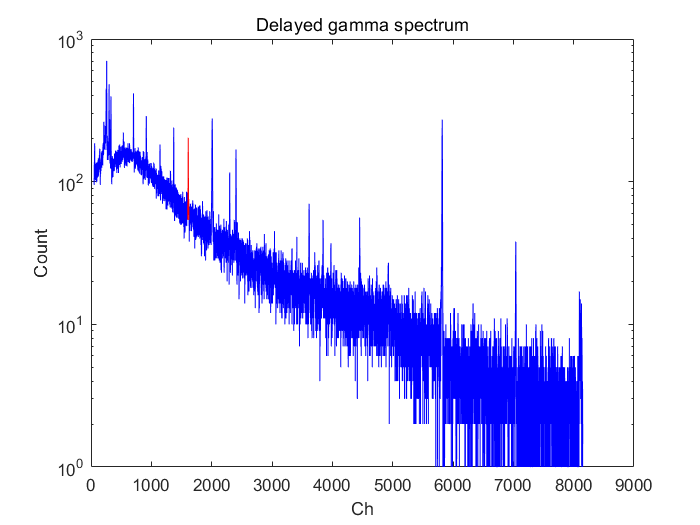

m = 19.1*1e-3; % g 纯核素质量
time_irr = 30*60; % s
time_cool = 1525*60; %s
time_det = 1440*60; %s
eff_peak = 0.158; % 峰效率
roi = [1603:1623];

%load('ng_Au.mat');
xs = 98.65; % barn
t_halflive = 2.69*24*60*60; %s
m_a = 197; % 质量数
e_charac = 0.411; % MeV
eff_branch = 0.9562; % 释放该特征能量的分支比

for i = 1:length(spec)
if mod(spec(i),1)~=0
    error('Spectrum should be count spec, not count rate spec');
end
end
figure;
semilogy(spec,'b');hold on;
semilogy(roi,spec(roi),'r-');
xlabel('Ch');
ylabel('Count');
title('Delayed gamma spectrum');

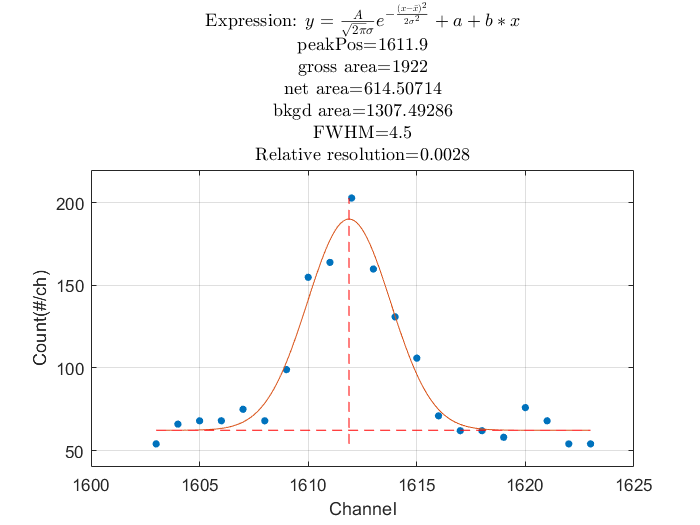

figure;
[area,bkgd,~,~,~] = fitPeak(roi,spec(roi),1); % 净计数与本底计数

lambda = log(2)/t_halflive;% /s
n_au = m/m_a*6.02e23;
factor_irr = 1-exp(-lambda*time_irr);
factor_cool = exp(-lambda*time_cool);
factor_det = 1-exp(-lambda*time_det);
% 计算注量率
flux = area/(n_au*xs*1e-24*factor_irr*factor_cool*factor_det/lambda)/eff_peak/eff_branch;

% 计算注量率不确定度
err_area = sqrt(area+2*bkgd); 
err_flux = err_area/(n_au*xs*1e-24*factor_irr*factor_cool*factor_det/lambda)/eff_peak/eff_branch;
disp(['Thermal neutron flux:',num2str(flux),'±',num2str(err_flux),' nv']);

Thermal neutron flux:2275.8586±210.4677 nv


## 注量率最小探测限from Currie equation

nb = bkgd; % 本底计数
nd = 4.65*sqrt(nb)+2.71; % Currie equation, fnr=fpr=5%
flux_lld = nd/(n_au*xs*1e-24*factor_irr*factor_cool*factor_det/lambda)/eff_peak/eff_branch;
disp(['Thermal neutron flux detection threshold:',num2str(flux_lld),' nv']);

Thermal neutron flux detection threshold:632.754 nv
